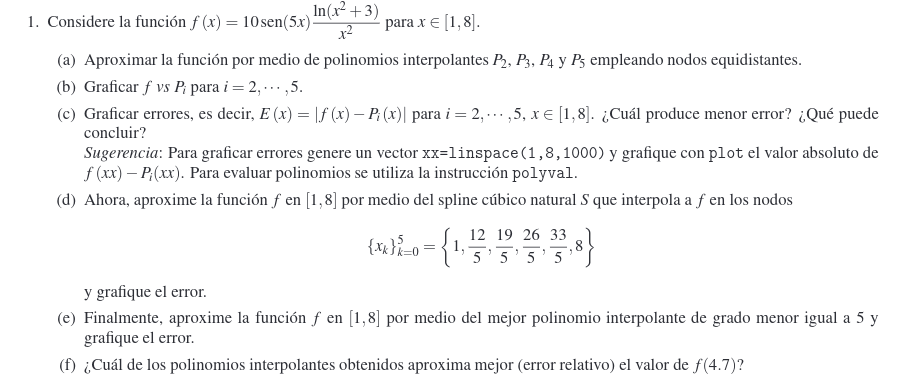

clf
syms f(x) 
f(x) = 10*sin(5*x)*(log(x^2+3)/x^2)

$$f(x) = \frac{10\,\sin\left(5\,x\right)\,\log\left(x^{2}+3\right)}{x^{2}}$$

%{
numero = 6

xx = linspace(1,8,numero)
yy = f(xx)

[C, L] = lagran (xx, yy)

C = double(C)

vpa(C,6)

xx_eval = linspace(1, 8, 100); % Puntos para evaluar el polinomio
yy_eval = polyval(C, xx_eval); % Evaluar el polinomio con los coeficientes

plot(xx_eval,yy_eval)
%}

%%% Spline cubico 
clf
rango = [1 8]

rango =      1     8


df1 = diff(f(x))

$$df1 = \frac{50\,\cos\left(5\,x\right)\,\log\left(x^{2}+3\right)}{x^{2}}+\frac{20\,\sin\left(5\,x\right)}{x\,\left(x^{2}+3\right)}-\frac{20\,\sin\left(5\,x\right)\,\log\left(x^{2}+3\right)}{x^{3}}$$

df2 = diff(df1,'r')

$$df2 = 0$$

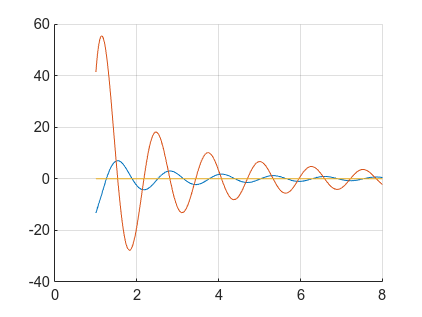

hold on 
grid on
fplot(f,rango)
fplot(df1,rango)
fplot(df2,rango)


xx = linspace(1,8,50)

xx =     1.0000    1.1429    1.2857    1.4286    1.5714    1.7143    1.8571    2.0000    2.1429    2.2857    2.4286    2.5714    2.7143    2.8571    3.0000    3.1429    3.2857    3.4286    3.5714    3.7143    3.8571    4.0000    4.1429    4.2857    4.4286    4.5714    4.7143    4.8571    5.0000    5.1429    5.2857    5.4286    5.5714    5.7143    5.8571    6.0000    6.1429    6.2857    6.4286    6.5714    6.7143    6.8571    7.0000    7.1429    7.2857    7.4286    7.5714    7.7143    7.8571    8.0000


yy = double(f(xx))

yy =   -13.2935   -6.0219    1.3475    6.0050    6.8809    4.5677    0.7491   -2.6465   -4.2410   -3.6609   -1.5231    0.9812    2.6798    2.9229    1.7954   -0.0164   -1.6040   -2.2686   -1.8100   -0.5614    0.8188    1.6801    1.6751    0.8891   -0.2403   -1.1569   -1.4523   -1.0420   -0.1764    0.7025    1.1823    1.0688    0.4605   -0.3204   -0.8941   -1.0055   -0.6341    0.0120    0.6097    0.8801    0.7164    0.2234   -0.3453   -0.7158   -0.7247   -0.3888    0.1125    0.5322    0.6754    0.4895



S=csnatural(xx,yy)

S =    55.7260         0   49.7642  -13.2935
 -245.1126   23.8826   53.1760   -6.0219
  -38.9484  -81.1657   44.9927    1.3475
   33.9474  -97.8579   19.4179    6.0050
  106.4219  -83.3090   -6.4630    6.8809
  117.8792  -37.6996  -23.7500    4.5677
   83.4545   12.8201  -27.3042    0.7491
   21.0514   48.5863  -18.5319   -2.6465
  -39.5921   57.6083   -3.3612   -4.2410
  -74.2307   40.6402   10.6743   -3.6609


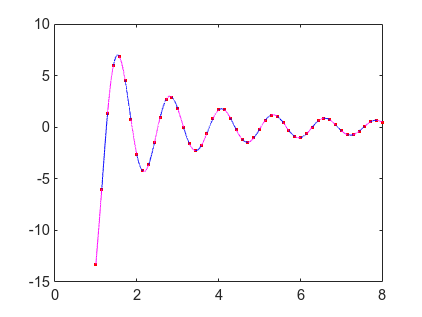

clf
GraficaCercha(xx,yy,S)

%fplot(f,[rango])
